Cluster participants into strategies using HBI responsibility, then compare their ratings (av_pdiv: average rating to the knowledge diversity combination; av_nodiv: average rating to the same knowledge combination) , and time across strategy clusters.

clear; clc;

projectDir = '/Users/foxxis/Desktop/HBI/exp1';

cd(projectDir);
addpath(projectDir);

addpath(fullfile(projectDir, 'src'));

## Load summary metrics

% Load the dataset and the hbi result
xlsx_file = '/Users/foxxis/Documents/social induction/experiment data/exp1/output100.xlsx';
hbi_file  = fullfile(projectDir, 'results', 'fitting', 'hbi_compare.mat');

% read the dataset
Sum = readtable(xlsx_file);
needVars = {'av_pdiv','av_nodiv','time','t','div_t','nodiv_t'};
Sum = Sum(:, needVars);
Sum.av_pdiv = Sum.av_pdiv * 2; % turn it into 0-100 scale
Sum.av_nodiv = Sum.av_nodiv * 2;

% read the hbi result
S = load(hbi_file);
cbm = S.cbm;
resp = cbm.output.responsibility; 

## Informativness Ratings

T = Sum(:, {'av_pdiv','av_nodiv'});
% descriptive statistics
desc = table(["pdiv";"nodiv"], ...
    [mean(T.av_pdiv,'omitnan'); mean(T.av_nodiv,'omitnan')], ...
    [std(T.av_pdiv,'omitnan'); std(T.av_nodiv,'omitnan')], ...
    'VariableNames', {'Condition','Mean','SD'});
disp(desc)

    Condition     Mean       SD  
    _________    ______    ______

     "pdiv"      63.743    19.433
     "nodiv"     36.257    19.433





within = table(["pdiv"; "nodiv"], 'VariableNames', {'Condition'});

% repeated-measures anova
rm = fitrm(T, 'av_pdiv-av_nodiv ~ 1', 'WithinDesign', within);
ranovatbl = ranova(rm, 'WithinModel', 'Condition');
disp(ranovatbl)

                                SumSq       DF       MeanSq            F           pValue       pValueGG      pValueHF      pValueLB 
                             ___________    ___    ___________    ___________    __________    __________    __________    __________

    (Intercept)                 5.05e+05      1       5.05e+05    -1.9631e+19             1             1             1             1
    Error                    -2.5724e-12    100    -2.5724e-14                                                                       
    (Intercept):Condition          38149      1          38149         50.511    1.7842e-10    1.7842e-10    1.7842e-10    1.7842e-10
    <s


SS_condition = ranovatbl.SumSq("(Intercept):Condition");
SS_error = ranovatbl.SumSq("Error(Condition)");
eta_p2 = SS_condition / (SS_condition + SS_error);
disp("eta_p2=" + string(eta_p2))

eta_p2=0.3356


## Cluster participants into strategies

% Names of the models in the same order as cbm.output.responsibility
% Mentalizing, VT, DW, KW, and Baseline
strategyNames = {'Mentalizing','VT','DW','KW','Baseline'};
nModels_expected = numel(strategyNames);
[respMax, stratIdx] = max(resp, [], 2);

% Force column vectors
respMax  = respMax(:);
stratIdx = stratIdx(:);

% strategy categorical
strategy = categorical(strategyNames(stratIdx), strategyNames);
strategy = strategy(:);

% strategyU (with Uncertain)
% The manuscript set confThr = 0.6
confThr = 0.6;
strategyU = categorical(strategyNames(stratIdx), [strategyNames, {'Uncertain'}]);
strategyU(respMax < confThr) = categorical({'Uncertain'});
strategyU = strategyU(:);

StratTbl = table(strategy, strategyU, respMax, stratIdx, ...
    'VariableNames', {'strategy','strategyU','respMax','stratIdx'});

% Convert responsibility matrix into a table with meaningful column names
RespTbl = array2table(resp, 'VariableNames', ...
    {'r_mentalizing','r_vt','r_dw','r_kw','r_baseline'});

% Combine the participants' data, strategy categorization, and
% responsiblity matrix into the same dataframe
A = [Sum, StratTbl, RespTbl];


% exclude Uncertain
A = A(A.strategyU ~= categorical({'Uncertain'}), :);


% Drop empty categories to avoid "jumping indices" in old functions
A.strategyU = removecats(A.strategyU);

## ANOVA

pA = 0.2310

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[1.7516e+03]}    {[ 3]}    {[583.8713]}    {[  1.4644]}    {[  0.2310]}
    {'Error' }    {[3.0301e+04]}    {[76]}    {[398.6992]}    {0×0 double}    {0×0 double}
    {'Total' }    {[3.2053e+04]}    {[79]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [8 19 39 14]
    source: 'anova1'
     means: [66.5000 68.9474 62.6410 54.6429]
        df: 76
         s: 19.9675


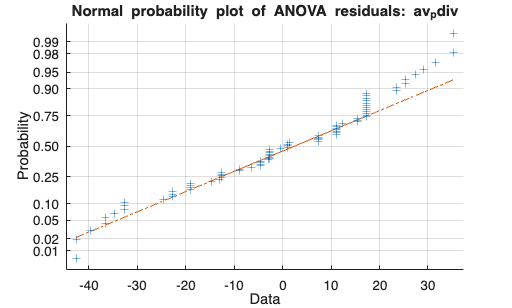

pA = 0.2310

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[1.7516e+03]}    {[ 3]}    {[583.8713]}    {[  1.4644]}    {[  0.2310]}
    {'Error' }    {[3.0301e+04]}    {[76]}    {[398.6992]}    {0×0 double}    {0×0 double}
    {'Total' }    {[3.2053e+04]}    {[79]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [8 19 39 14]
    source: 'anova1'
     means: [33.5000 31.0526 37.3590 45.3571]
        df: 76
         s: 19.9675


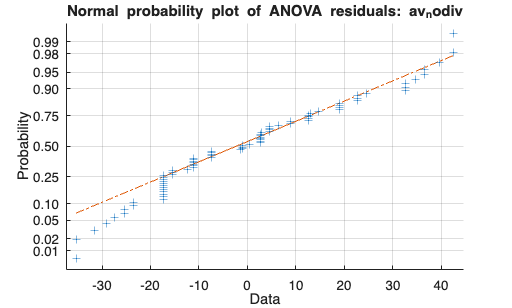

pA = 0.1960

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 0.9332]}    {[ 3]}    {[  0.3111]}    {[  1.6017]}    {[  0.1960]}
    {'Error' }    {[14.7602]}    {[76]}    {[  0.1942]}    {0×0 double}    {0×0 double}
    {'Total' }    {[15.6934]}    {[79]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [8 19 39 14]
    source: 'anova1'
     means: [6.7379 6.5547 6.7765 6.8681]
        df: 76
         s: 0.4407


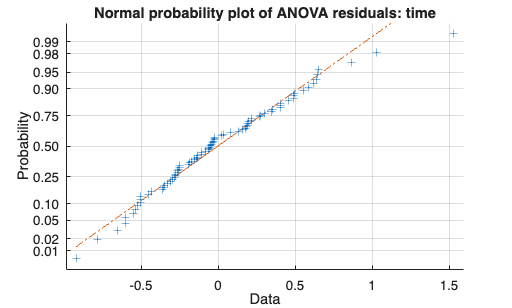

pA = 0.7083

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 1.0415]}    {[ 3]}    {[  0.3472]}    {[  0.4639]}    {[  0.7083]}
    {'Error' }    {[56.8756]}    {[76]}    {[  0.7484]}    {0×0 double}    {0×0 double}
    {'Total' }    {[57.9171]}    {[79]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [8 19 39 14]
    source: 'anova1'
     means: [4.9454 4.6191 4.8499 4.6791]
        df: 76
         s: 0.8651


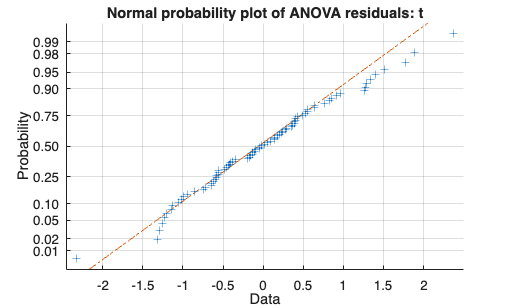

pA = 0.3725

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 2.9978]}    {[ 3]}    {[  0.9993]}    {[  1.0569]}    {[  0.3725]}
    {'Error' }    {[71.8534]}    {[76]}    {[  0.9454]}    {0×0 double}    {0×0 double}
    {'Total' }    {[74.8512]}    {[79]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [8 19 39 14]
    source: 'anova1'
     means: [4.0057 3.4505 3.8763 3.8918]
        df: 76
         s: 0.9723


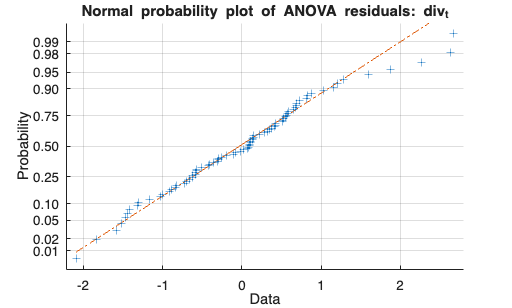

pA = 0.7841

tbl = 4×6 cell array
    {'Source'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Groups'}    {[ 0.8343]}    {[ 3]}    {[  0.2781]}    {[  0.3572]}    {[  0.7841]}
    {'Error' }    {[59.1719]}    {[76]}    {[  0.7786]}    {0×0 double}    {0×0 double}
    {'Total' }    {[60.0062]}    {[79]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: {4×1 cell}
         n: [8 19 39 14]
    source: 'anova1'
     means: [4.2246 4.1434 4.2521 3.9743]
        df: 76
         s: 0.8824


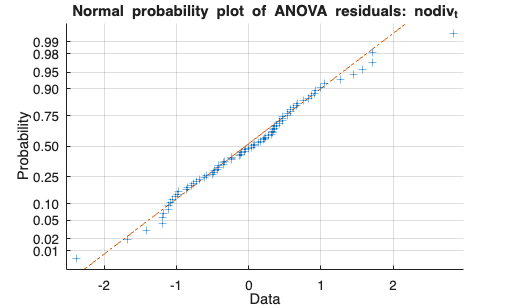

metrics = {'av_pdiv','av_nodiv','time','t','div_t','nodiv_t'};
logMetrics = {'time','t','div_t','nodiv_t'}; % use log transform for time
% meaning of each metric
% av_pdiv: rating of informativeness for pairs with knowledge diversity
% av_nodiv: rating of informativeness for pairs with no knowledge diversity
% time: time for completing the experiment
% time for completing the trials
% div_t: time for completing the trials interacting with informants with
% knowledge diversity
% nodiv_t: time for completing the trials interacting with informants with
% no knowledge diversity

minGroupN = 5;  % if a strategy group includes less than 5 participants, exclude that group from analysis

% prepare the output
R = cell(0,6);               

% Use log transform for time metrics


for k = 1:numel(metrics)
    % For each metric, organize participant-level values and their assigned
    % category labels for comparison
    yName = metrics{k};
    y = A.(yName);
    g = A.strategyU;

    if ismember(yName, logMetrics)
      y = log(y);
      yNameOut = [yName '_log'];
    else
      yNameOut = yName;
    end

    % Remove groups with fewer than minGroupN participants
    [gID, ~] = findgroups(g);
    grpN = accumarray(gID, 1);
    keepGroup = grpN >= minGroupN;
    keepObs = keepGroup(gID);

    % Recompute groups after excluding small groups
    y = y(keepObs);
    g = g(keepObs);
    [gID, gNames] = findgroups(g);

    K = numel(gNames);
    % If there are less than 2 categories, skip the anova analysis
    if K < 2
        warning('%s: <2 groups; skipped.', yName); 
        continue;
    end

    % One-way ANOVA
    [pA, tbl, stats] = anova1(y, gID,'off')
    eta2 = tbl{2,2} / tbl{4,2};
    Fstat = tbl{2,5};
    
    % Normality check using residuals
    groupMean = splitapply(@mean, y, gID);
    residuals = y - groupMean(gID);
    figure;
    normplot(residuals);
    title(sprintf('Normal probability plot of ANOVA residuals: %s', yName));

    R(end+1,:) = {yName, numel(y), K, Fstat, pA, eta2}; 
end


Results = cell2table(R, 'VariableNames', {'metric','N','kGroups','F', 'p_anova','eta2'});

disp('===ANOVA Summary===');

===ANOVA Summary===


disp(Results);

       metric       N     kGroups       F       p_anova      eta2  
    ____________    __    _______    _______    _______    ________

    {'av_pdiv' }    80       4        1.4644    0.23095    0.054648
    {'av_nodiv'}    80       4        1.4644    0.23095    0.054648
    {'time'    }    80       4        1.6017    0.19599    0.059465
    {'t'       }    80       4        0.4639    0.70832    0.017982
    {'div_t'   }    80       4        1.0569     0.3725    0.040051
    {'nodiv_t' }    80       4       0.35718    0.78407    0.013903



needVars = {'av_pdiv','av_nodiv','time','t','div_t','nodiv_t'};
group_descriptives(A, needVars);

=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_time    sd_time    sem_time    n_time    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________

## Robustness Check using different confThr

% strategyU (with Uncertain)
confThrList = [0,0.2,0.4,0.8];
% Store results across all thresholds
R = cell(0,8);

for c = 1:numel(confThrList)
    confThr = confThrList(c);
    strategyU = categorical(strategyNames(stratIdx), [strategyNames, {'Uncertain'}]);
    strategyU(respMax < confThr) = categorical({'Uncertain'});
    strategyU = strategyU(:);
    
    StratTbl = table(strategy, strategyU, respMax, stratIdx, ...
        'VariableNames', {'strategy','strategyU','respMax','stratIdx'});
    
    % Convert responsibility matrix into a table with meaningful column names
    RespTbl = array2table(resp, 'VariableNames', ...
        {'r_mentalizing','r_vt','r_dw','r_kw','r_baseline'});
    
    % Combine the participants' data, strategy categorization, and
    % responsiblity matrix into the same dataframe
    A = [Sum, StratTbl, RespTbl];
    
    
    % exclude Uncertain
    A = A(A.strategyU ~= categorical({'Uncertain'}), :);
    
    
    % Drop empty categories to avoid "jumping indices" in old functions
    A.strategyU = removecats(A.strategyU);
    
    metrics = {'av_pdiv','av_nodiv','time','t','div_t','nodiv_t'};
    
    logMetrics = {'time','t','div_t','nodiv_t'}; % use log transform for time
    % meaning of each metric
    % av_pdiv: rating of informativeness for pairs with knowledge diversity
    % av_nodiv: rating of informativeness for pairs with no knowledge diversity
    % time: time for completing the experiment
    % t: time for completing the trials
    % div_t: time for completing the trials interacting with informants with
    % knowledge diversity
    % nodiv_t: time for completing the trials interacting with informants with
    % no knowledge diversity
    
    minGroupN = 5;  % if a strategy group includes less than 5 participants, exclude that group from analysis
    

    % Use log transform for time metrics
    
    
    for k = 1:numel(metrics)
        % For each metric, organize participant-level values and their assigned
        % category labels for comparison
        yName = metrics{k};
        y = A.(yName);
        g = A.strategyU;
    
        if ismember(yName, logMetrics)
          y = log(y);
          yNameOut = [yName '_log'];
        else
          yNameOut = yName;
        end
    
        % Remove groups with fewer than minGroupN participants
        [gID, ~] = findgroups(g);
        grpN = accumarray(gID, 1);
        keepGroup = grpN >= minGroupN;
        keepObs = keepGroup(gID);
    
        % Recompute groups after excluding small groups
        y = y(keepObs);
        g = g(keepObs);
        [gID, gNames] = findgroups(g);
    
        K = numel(gNames);
        % If there are less than 2 categories, skip the anova analysis
        if K < 2
            warning('%s: <2 groups; skipped.', yName); 
            continue;
        end
    
        % One-way ANOVA
        [pA, tbl, stats] = anova1(y, gID,'off');
        eta2 = tbl{2,2} / tbl{4,2};
        Fstat = tbl{2,5};
        
        includedGroups = strjoin(string(gNames), ', ');

        R(end+1,:) = {confThr, yNameOut, numel(y), K, ...
                     includedGroups, Fstat, pA, eta2};
    end
    
    
    needVars = {'av_pdiv','av_nodiv','time','t','div_t','nodiv_t'
        };
    fprintf('\n=== Group descriptives: confThr = %.2f ===\n', confThr);
    group_descriptives(A, needVars);
end


=== Group descriptives: confThr = 0.00 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_time    sd_time    sem_time    n_time    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________


=== Group descriptives: confThr = 0.20 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_time    sd_time    sem_time    n_time    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________


=== Group descriptives: confThr = 0.40 ===


=== Group descriptives (mean, SEM) ===
       strategyU       N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_time    sd_time    sem_time    n_time    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    _______________    __    ____________    __________    ___________    _________


=== Group descriptives: confThr = 0.80 ===


=== Group descriptives (mean, SEM) ===
     strategyU      N     mean_av_pdiv    sd_av_pdiv    sem_av_pdiv    n_av_pdiv    mean_av_nodiv    sd_av_nodiv    sem_av_nodiv    n_av_nodiv    mean_time    sd_time    sem_time    n_time    mean_t     sd_t     sem_t     n_t    mean_div_t    sd_div_t    sem_div_t    n_div_t    mean_nodiv_t    sd_nodiv_t    sem_nodiv_t    n_nodiv_t
    ____________    __    ____________    __________    ___________    _________   


% Combine results from all thresholds
RobustResults = cell2table(R, 'VariableNames', ...
    {'confThr','metric','N','kGroups','includedGroups', ...
     'F','p_anova','eta2'});

% Place different thresholds for the same metric together
RobustResults = sortrows(RobustResults, {'metric','confThr'});

disp('=== ANOVA robustness across confidence thresholds ===');

=== ANOVA robustness across confidence thresholds ===


disp(RobustResults);

    confThr        metric          N     kGroups            includedGroups                F       p_anova      eta2   
    _______    _______________    ___    _______    _______________________________    _______    _______    _________

        0      {'av_nodiv'   }    101       4       "Mentalizing, VT, KW, Baseline"     1.6614    0.18041     0.048871
      0.2      {'av_nodiv'   }    101       4       "Mentalizing, VT, KW, Baseline"     1.6614    0.18041     0.048871
      0.4      {'av_nodiv'   }     98       4       "Mentalizing, VT, KW, Baseline"     2.0235    0.11589     0.060663
      0.8      {'av_nodiv'   }     50       3       "VT, KW, Baseline"                 0.41061     0.6656     0.017173
        0    

helper function

function group_descriptives(A, needVars)

% Exclude strategy groups with fewer than 5 participants
g = A.strategyU;
groupNames = categories(g);
groupN = countcats(g);
keepGroups = groupNames(groupN >= 5);

A = A(ismember(g, keepGroups), :);
A.strategyU = removecats(A.strategyU);

% Recompute group indices after filtering
g = A.strategyU;
[Gid, gLabels] = grp2idx(g);

Desc = table(gLabels(:), accumarray(Gid, 1), 'VariableNames', {'strategyU','N'});

for i = 1:numel(needVars)
    yName = needVars{i};
    y = A.(yName);

    m = splitapply(@mean, y, Gid);
    sd = splitapply(@std, y, Gid);
    n = splitapply(@numel, y, Gid);
    sem = sd ./ sqrt(n);

    Desc.(['mean_' yName]) = m;
    Desc.(['sd_' yName]) = sd;
    Desc.(['sem_' yName]) = sem;
    Desc.(['n_' yName]) = n;
end

disp('=== Group descriptives (mean, SEM) ===');
disp(Desc);

end